clc
clear

N = 10;
x = mvnrnd([1; 4], [.3 .2 ; .2 .3], N);
y = mvnrnd([3; 1], [.3 .1 ; .1 .3], N);
data = [x; y];
label = [zeros(1,N) ones(1,N)]';
[W mu] = LDA_reduce(1, data, label, [N;N]);
newData = reduceData(data, W);

alpha = (W(2)-0)/(W(1)-0);
f = @(x) alpha * x ;
f2 = @(x) alpha * x + 1;
t = linspace(-3, 1, 1000);
t2 = linspace(-2,2,1000);
labels = [zeros(N,1) ; ones(N,1);]

labels =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


meanalpha = (mu(3,2)-mu(1,2))/(mu(3,1)-mu(1,1));
fmean = @(x) meanalpha * x + (mu(1,2) - mu(1,1)*meanalpha);

mid = [mu(1,1) + (mu(3,1)-mu(1,1))/2 , mu(2,1) + (mu(3,1)-mu(2,1))/2];

P = W*inv(W' * W)*W';
projected_data = P * data(:,:)'

projected_data =    -1.2141   -1.5155   -1.3689   -1.4495   -1.5598   -1.3301   -1.4281   -1.5241   -1.1529   -1.6657    0.5876    0.4465    0.4298    0.5755    0.4636    0.4776    0.7563    0.2306    0.2957    0.1827
    2.0944    2.6144    2.3616    2.5006    2.6909    2.2947    2.4637    2.6294    1.9890    2.8736   -1.0137   -0.7704   -0.7415   -0.9929   -0.7997   -0.8239   -1.3048   -0.3978   -0.5102   -0.3152


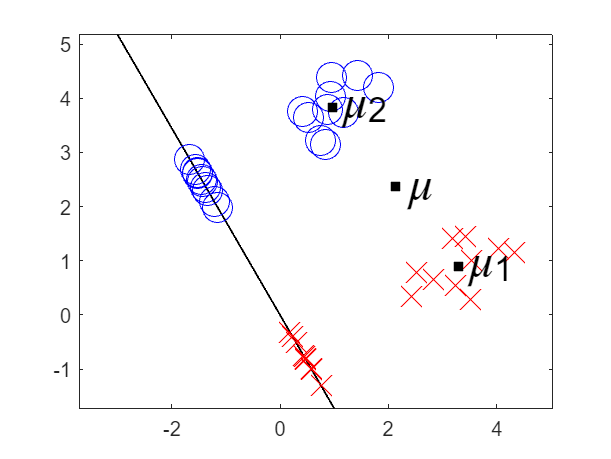


% Points
gscatter(data(:,1), data(:,2),labels,'br','ox',15)
hold on
% Subspace
plot(t,f(t),LineWidth=1,Color=[0,0,0])
% projected data
gscatter(projected_data(1,:),projected_data(2,:),labels,'br','ox',15)
% Means
scatter(mu(1,1), mu(1,2),'square','filled','black')
text(mu(1,1)+.1, mu(1,2)+.1,'\mu_2','FontSize',24)
scatter(mu(2,1), mu(2,2),'square','filled','black')
text(mu(2,1)+.1, mu(2,2)+.1,'\mu_1','FontSize',24)
scatter(mu(3,1), mu(3,2),'square','filled','black')
text(mu(3,1)+.1, mu(3,2)+.1,'\mu','FontSize',24)
% mean lines
% quiver(mu(1,1),mu(1,2),mu(3,1)-mu(1,1),mu(3,2) - mu(1,2),0,LineWidth=1,Color=[0,0,0],MaxHeadSize=.3)
% quiver(mu(3,1),mu(3,2),mu(1,1)-mu(3,1),mu(1,2) - mu(3,2),0,LineWidth=1,Color=[0,0,0],MaxHeadSize=.3)
% quiver(mu(2,1),mu(2,2),mu(3,1)-mu(2,1),mu(3,2) - mu(2,2),0,LineWidth=1,Color=[0,0,0],MaxHeadSize=.3)
% quiver(mu(3,1),mu(3,2),mu(2,1)-mu(3,1),mu(2,2) - mu(3,2),0,LineWidth=1,Color=[0,0,0],MaxHeadSize=.3)
% text(mid(2),fmean(mid(2)),'S_B^2')
% text(mid(1),fmean(mid(1)),'S_B^1')

xlim([-2 5])
axis equal
legend off
hold off

function [W mu] = LDA_reduce(D, train, trainLabel, Nk)
    % Calculate mean of each class
    for i=1:2
        mu(i,:)= mean(train(trainLabel == i-1,:));
    end
    % Calculate total mean
    mu(3,:) = mean(train);

    % Calculate within-class scattesr
    Sw = 0;
    for j=1:size(mu,1)-1
        Sw = Sw + (train(find(trainLabel==j),:)' - mu(j,:)') * (train(find(trainLabel==j),:)' - mu(j,:)')';
    end
    % Calculate between-class scatter
    Sb = Nk .* (mu(1:2,:)' - mu(3,:)') * (mu(1:2,:)' - mu(3,:)')';

    % Use the eigenvalue decomposition and sort it in decending order
    [V e] = eig(Sb,Sw);
    [B,I] = sort(diag(e),'descend');
    
    % Take D number of eigenvectores corresponding to the largest values
    for i=1:D
        W(:,i) = V(:,I(i));
    end
end
% Reduces the data to the given dimension of W
function newData = reduceData(data, W)
    data = double(data);
    newData = data * W;
end
